# Aircraft 3D Animation Function

function [] = aircraft_3d_animation(...
    model_mat_file, ...
    heading_deg, ...
    pitch_deg, ...
    bank_deg, ...
    roll_command, ...
    pitch_command, ...
    angle_of_attack_deg, ...
    angle_of_sideslip_deg, ...
    fligh_path_angle_deg, ...
    mach, ...
    altitude_ft, ...
    nz_g,  ...
    controls_deflection_deg, ...
    frame_time, ...
    speedx, ...
    isave_movie, ...
    movie_file_name)


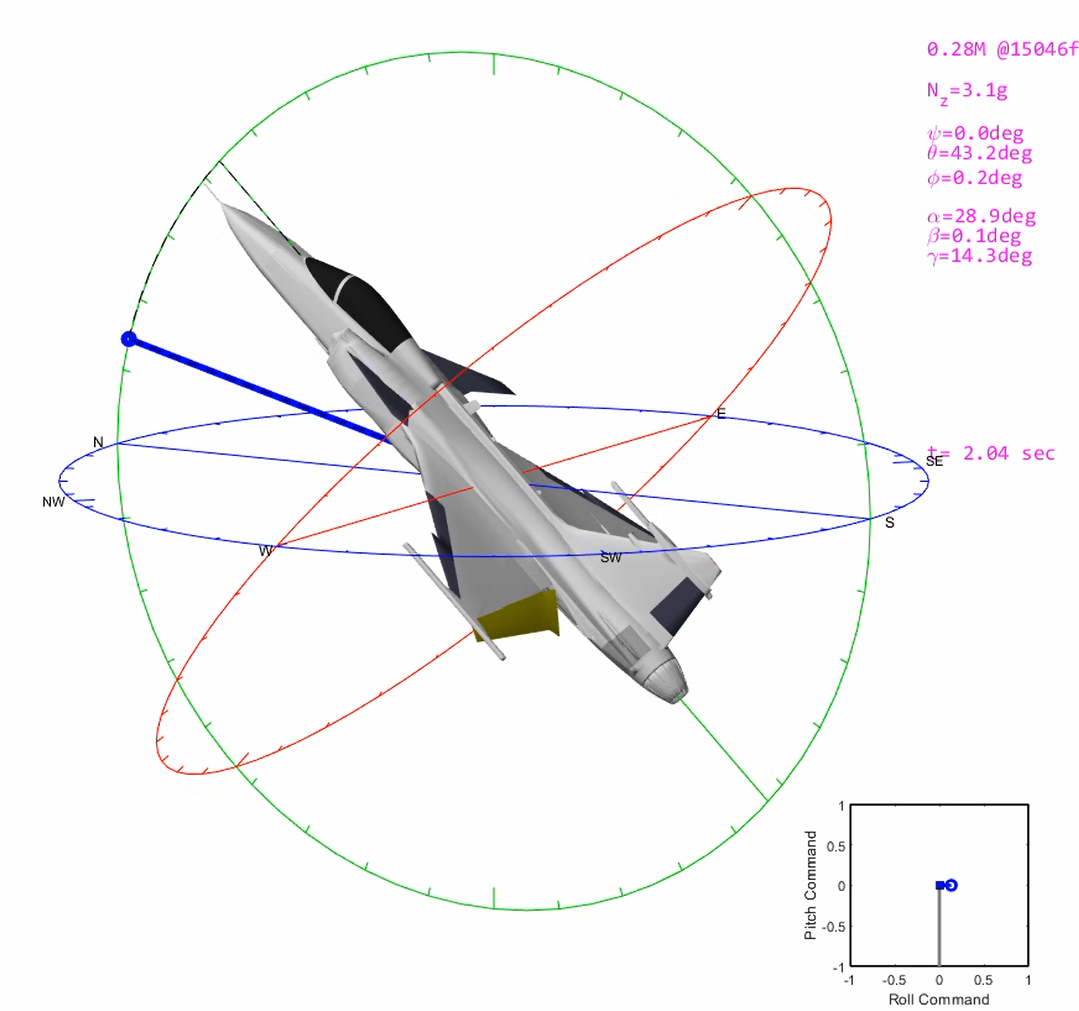

%% Function Name: aircraft_3d_animation
%
% Description: A visualization tool that animates a 3D model using
% flight or simulation data
%
% Assumptions: None
%
% Inputs:
%     model_mat_file			Mat file containing the Model3D structure.
%                               (see "./import_stl_model/import_stl_model.m")
%                               This structure must have the following fields:
%                                 - Aircraft: a structure vector containing:
%                                      * stl_data.vertices (vertices information for the
%                                                           patch command)
%                                      * stl_data.faces  (faces information for the patch command)
%                                      * model: stl file (string)
%                                      * color: surface color
%                                      * alpha: transparency
%                                 - Controls: a structure vector containing:
%                                      * stl_data.vertices (vertices information for the
%                                                           patch command)
%                                      * stl_data.faces  (faces information for the patch command)
%                                      * model: stl file (string)
%                                      * label: string
%                                      * color: surface color
%                                      * rot_offset_deg:
%                                      * rot_point:
%                                      * rot_vect:
%                                      * max_deflection:
%     heading_deg:              Heading angle [deg]
%     pitch_deg:                Pitch angle [deg]
%     bank_deg:                 Roll angle [deg]
%     roll_command:             Roll  stick command [-1,+1] [-1 -> left,            +1 -> right]
%     pitch_command:            Pitch stick command [-1,+1] [-1 -> full-back stick, +1 -> full-fwd stick]
%     angle_of_attack_deg:      AoA [deg]
%     angle_of_sideslip_deg:    AoS [deg]
%     fligh_path_angle_deg:     Flight path angle [deg]
%     mach:                     Mach number [airspeed/speed_of_sound]
%     altitude_ft:              Altitude [ft]
%     nz_g:                     Vertical load factor [g]
%     controls_deflection_deg:  Flight control deflection (deg) (each column is a different control surface)
%     frame_time:               Sample time [sec]
%     speedx:                   Reproduction speed factor
%     isave_movie:              Save the animation in a movie file? 0-1
%     movie_file_name:          Movie file name
%
% Outputs:
%     none
%
% $Revision: R2018b$
% $Author: Rodney Rodriguez Robles$
% $Date: January 25, 2021$
%------------------------------------------------------------------------------------------------------------

## 1. Loading the *.mat 3D model

% Select and load 3D model (see "generate_mat_from_stl.m" for examples)
load(model_mat_file, 'Model3D');

## 2. Initializing the Video Object

% Open the video output if we are recording the movie
if isave_movie == 1
    aviobj = VideoWriter(movie_file_name, 'MPEG-4');
    aviobj.Quality = 100;  % movie quality
    aviobj.FrameRate = 1/frame_time;
    open(aviobj);
end

## 3. Get the Model Dimensions and Initialize the Figure

% Get maximum dimension including all the aircraft's parts
AC_DIMENSION = max(max(sqrt(sum(Model3D.Aircraft(1).stl_data.vertices.^2, 2))));
for i=1:length(Model3D.Control)
    AC_DIMENSION = max(AC_DIMENSION, max(max(sqrt(sum(Model3D.Control(i).stl_data.vertices.^2, 2)))));
end

%% Initialize the figure
hf = figure;
AX = axes('position',[0.0 0.0 1 1]);
axis off
scrsz = get(0, 'ScreenSize');
set(gcf, 'Position',[scrsz(3)/40 scrsz(4)/12 scrsz(3)/2*1.0 scrsz(3)/2.2*1.0], 'Visible', 'on');
set(AX, 'color', 'none');
axis('equal')
hold on;
cameratoolbar('Show')

## 4. Initailize the Transformation Groups

% Initializate transformation group handles
% -------------------------------------------------------------------------
% Aircraft transformation group handle
AV_hg         = hgtransform;
% controls_deflection_deg transformation group handles
CONT_hg       = zeros(1,length(Model3D.Control));
for i=1:length(Model3D.Control)
    CONT_hg(i) = hgtransform('Parent', AV_hg, 'tag', Model3D.Control(i).label);
end
% Circles around the aircraft transformation group handles
euler_hgt(1)  = hgtransform('Parent',           AX, 'tag', 'OriginAxes');
euler_hgt(2)  = hgtransform('Parent', euler_hgt(1), 'tag', 'roll_disc');
euler_hgt(3)  = hgtransform('Parent', euler_hgt(1), 'tag', 'pitch_disc');
euler_hgt(4)  = hgtransform('Parent', euler_hgt(1), 'tag', 'heading_disc');
euler_hgt(5)  = hgtransform('Parent', euler_hgt(2), 'tag', 'roll_line');
euler_hgt(6)  = hgtransform('Parent', euler_hgt(3), 'tag', 'pitch_line');
euler_hgt(7)  = hgtransform('Parent', euler_hgt(4), 'tag', 'heading_line');

## 5. Plot the 3D Objects 

% Plot objects
% -------------------------------------------------------------------------
% Plot airframe
AV = zeros(1, length(Model3D.Aircraft));
for i = 1:length(Model3D.Aircraft)
    AV(i) = patch(Model3D.Aircraft(i).stl_data,  ...
        'FaceColor',        Model3D.Aircraft(i).color, ...
        'EdgeColor',        'none',        ...
        'FaceLighting',     'gouraud',     ...
        'AmbientStrength',   0.15,          ...
        'LineSmoothing',    'on',...
        'Parent',            AV_hg, ...
        'LineSmoothing', 'on');
end
CONT = zeros(1, (length(Model3D.Control)));
% Plot controls_deflection_deg
for i=1:length(Model3D.Control)
    CONT(i) = patch(Model3D.Control(i).stl_data,  ...
        'FaceColor',        Model3D.Control(i).color, ...
        'EdgeColor',        'none',        ...
        'FaceLighting',     'gouraud',     ...
        'AmbientStrength',  0.15,          ...
        'LineSmoothing', 'on',...
        'Parent',           CONT_hg(i));
end
% Fixing the axes scaling and setting a nice view angle
axis('equal');
axis([-1, 1, -1, 1, -1, 1] * 2.0 * AC_DIMENSION)
set(gcf, 'Color', [1, 1, 1])
axis off
view([30, 10])
zoom(2.0);
% Add a camera light, and tone down the specular highlighting
camlight('left');
material('dull');

## 6. Plot 3D Visual References

%% Plot Euler angles references
R = AC_DIMENSION;

% Plot outer circles
phi = (-pi:pi/36:pi)';
D1 = [sin(phi) cos(phi) zeros(size(phi))];
% Heading disc
plot3(R * D1(:,1), R * D1(:,2), R * D1(:,3), 'Color', 'b', 'tag', 'Zplane', 'Parent', euler_hgt(4));
% Pitch disc
plot3(R * D1(:,2), R * D1(:,3), R * D1(:,1), 'Color', [0, 0.8, 0], 'tag', 'Yplane', 'Parent', euler_hgt(3));
% Roll disc
plot3(R * D1(:,3), R * D1(:,1), R * D1(:,2), 'Color', 'r', 'tag', 'Xplane', 'Parent', euler_hgt(2));

% Plot +0,+90,+180,+270 Marks
S = 0.95;
phi = -pi+pi/2:pi/2:pi;
D1 = [sin(phi); cos(phi); zeros(size(phi))];
plot3([S * R * D1(1, :); R * D1(1, :)],[S * R * D1(2, :); R * D1(2, :)],[S * R * D1(3, :); R * D1(3, :)], 'Color', 'b', 'tag', 'Zplane', 'Parent', euler_hgt(4));
plot3([S * R * D1(2, :); R * D1(2, :)],[S * R * D1(3, :); R * D1(3, :)],[S * R * D1(1, :); R * D1(1, :)], 'Color',[0 0.8 0], 'tag', 'Yplane', 'Parent', euler_hgt(3));
plot3([S * R * D1(3, :); R * D1(3, :)],[S * R * D1(1, :); R * D1(1, :)],[S * R * D1(2, :); R * D1(2, :)], 'Color', 'r', 'tag', 'Xplane', 'Parent', euler_hgt(2));
text(R * 1.05 * D1(1, :), R * 1.05 * D1(2, :), R * 1.05 * D1(3, :), {'N', 'E', 'S', 'W'}, 'Fontsize',9, 'color', [0 0 0], 'HorizontalAlign', 'center', 'VerticalAlign', 'middle');

% Plot +45,+135,+180,+225,+315 Marks
S = 0.95;
phi = -pi+pi/4:2*pi/4:pi;
D1 = [sin(phi); cos(phi); zeros(size(phi))];
plot3([S*R * D1(1, :); R * D1(1, :)],[S*R * D1(2, :); R * D1(2, :)],[S*R * D1(3, :); R * D1(3, :)], 'Color', 'b', 'tag', 'Zplane', 'Parent',euler_hgt(4));
text(R * 1.05 * D1(1, :), R * 1.05 * D1(2, :), R * 1.05 * D1(3, :), {'NW', 'NE', 'SE', 'SW'}, 'Fontsize',8, 'color',[0 0 0], 'HorizontalAlign', 'center', 'VerticalAlign', 'middle');

% 10 deg sub-division marks
S = 0.98;
phi = -180:10:180;
phi = phi*pi / 180;
D1 = [sin(phi); cos(phi); zeros(size(phi))];
plot3([S * R * D1(1, :); R * D1(1, :)],[S * R * D1(2, :); R * D1(2, :)],[S * R * D1(3, :); R * D1(3, :)], 'Color', 'b', 'tag', 'Zplane', 'Parent', euler_hgt(4));
plot3([S * R * D1(2, :); R * D1(2, :)],[S * R * D1(3, :); R * D1(3, :)],[S * R * D1(1, :); R * D1(1, :)], 'Color', [0 0.8 0], 'tag', 'Yplane', 'Parent', euler_hgt(3));
plot3([S * R * D1(3, :); R * D1(3, :)],[S * R * D1(1, :); R * D1(1, :)],[S * R * D1(2, :); R * D1(2, :)], 'Color', 'r', 'tag', 'Xplane', 'Parent', euler_hgt(2));

% Guide lines
plot3([-R, R], [ 0, 0], [0, 0], 'b-', 'tag', 'heading_line', 'parent', euler_hgt(7));
plot3([-R, R], [ 0, 0], [0 ,0], 'g-', 'tag',   'pitch_line', 'parent', euler_hgt(6), 'color',[0 0.8 0]);
plot3([ 0, 0], [-R, R], [0, 0], 'r-', 'tag',    'roll_line', 'parent', euler_hgt(5));

## 7. Text with Time-Varying Values

% Initialize text handles
FontSize    = 13;
text_color  = [1, 0, 1];
font_name   = 'Consolas';
hdle_text_t                 = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 't=  0 sec', 'Color',text_color, 'FontSize',FontSize, 'FontName', font_name);
hdle_text_valtitude         = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 0.63 * AC_DIMENSION * 1.5, '', 'Color',text_color, 'FontSize', FontSize, 'FontName', font_name);
hdle_text_psi_deg           = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 0.50 * AC_DIMENSION * 1.5, '', 'Color',text_color, 'FontSize', FontSize, 'FontName', font_name);
hdle_text_th                = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 0.47 * AC_DIMENSION * 1.5, '', 'Color',text_color, 'FontSize', FontSize, 'FontName', font_name);
hdle_text_phi               = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 0.43 * AC_DIMENSION * 1.5, '', 'Color',text_color, 'FontSize', FontSize, 'FontName', font_name);
hdle_text_angle_of_attack   = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 0.37 * AC_DIMENSION * 1.5, '', 'Color',text_color, 'FontSize', FontSize, 'FontName', font_name);
hdle_text_angle_of_sideslip = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 0.34 * AC_DIMENSION * 1.5, '', 'Color',text_color, 'FontSize', FontSize, 'FontName', font_name);
hdle_text_gam               = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 0.31 * AC_DIMENSION * 1.5, '', 'Color',text_color, 'FontSize', FontSize, 'FontName', font_name);
hdle_text_nz                = text(0.45 * AC_DIMENSION * 1.5, 0.55 * AC_DIMENSION * 1.5, 0.56 * AC_DIMENSION * 1.5, '', 'Color',text_color, 'FontSize', FontSize, 'FontName', font_name);

## 8. Aerodynamic Speed Vector (Angle of Attack and Angle of Sideslip)

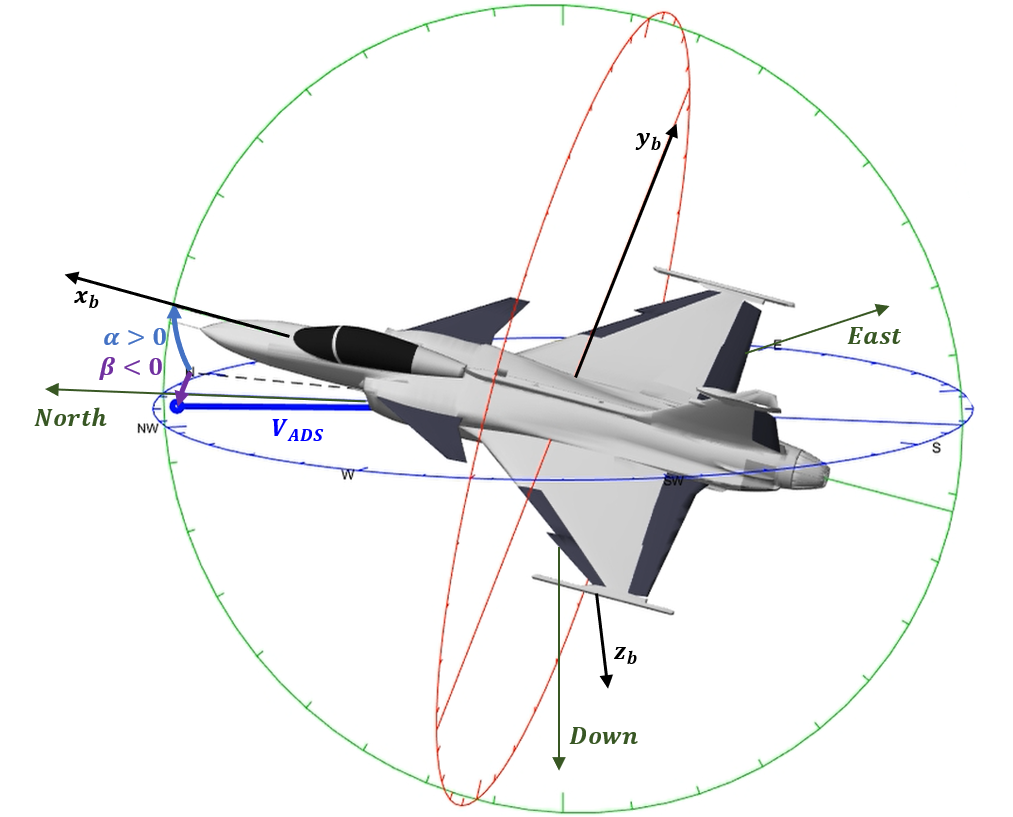

% Aerodynamic Speed Vector initialization
Lbh_i = Lbh(heading_deg(1), pitch_deg(1), bank_deg(1));
Vaer  = Lbh_i' * Lbw(angle_of_attack_deg(1), angle_of_sideslip_deg(1)) * [AC_DIMENSION; 0; 0];
X_aer = [0, -Vaer(1)];
Y_aer = [0, +Vaer(2)];
Z_aer = [0, -Vaer(3)];

Vaer_angle_of_sideslip0  = Lbh_i' * Lbw(angle_of_attack_deg(i), 0) * [AC_DIMENSION; 0; 0];
X_aer_angle_of_sideslip0 = [0, -Vaer_angle_of_sideslip0(1), -Vaer(1)];
Y_aer_angle_of_sideslip0 = [0, +Vaer_angle_of_sideslip0(2), +Vaer(2)];
Z_aer_angle_of_sideslip0 = [0, -Vaer_angle_of_sideslip0(3), -Vaer(3)];

Vaer_angle_of_attack0angle_of_sideslip0  = Lbh_i' * Lbw(0, 0) * [AC_DIMENSION; 0; 0];
X_aer_angle_of_attack0angle_of_sideslip0 = [0, -Vaer_angle_of_attack0angle_of_sideslip0(1), -Vaer_angle_of_sideslip0(1)];
Y_aer_angle_of_attack0angle_of_sideslip0 = [0, +Vaer_angle_of_attack0angle_of_sideslip0(2), +Vaer_angle_of_sideslip0(2)];
Z_aer_angle_of_attack0angle_of_sideslip0 = [0, -Vaer_angle_of_attack0angle_of_sideslip0(3), -Vaer_angle_of_sideslip0(3)];

hdle_aero = plot3(X_aer, Y_aer, Z_aer, 'b-o', 'XDataSource', 'X_aer', 'YDataSource', 'Y_aer', 'ZDataSource', 'Z_aer', 'linewidth', 4);
hdle_aero_angle_of_sideslip0 = plot3(X_aer_angle_of_sideslip0, Y_aer_angle_of_sideslip0, Z_aer_angle_of_sideslip0, '--', 'Color', [1 1 1]*0, 'XDataSource', 'X_aer_angle_of_sideslip0', 'YDataSource', 'Y_aer_angle_of_sideslip0', 'ZDataSource', 'Z_aer_angle_of_sideslip0', 'linewidth', 0.3);
hdle_aero_angle_of_attack0angle_of_sideslip0 = plot3(X_aer_angle_of_attack0angle_of_sideslip0, Y_aer_angle_of_attack0angle_of_sideslip0, Z_aer_angle_of_attack0angle_of_sideslip0, '--', 'Color', [1 1 1]*0, 'XDataSource', 'X_aer_angle_of_attack0angle_of_sideslip0', 'YDataSource', 'Y_aer_angle_of_attack0angle_of_sideslip0', 'ZDataSource', 'Z_aer_angle_of_attack0angle_of_sideslip0', 'linewidth', 0.3);

## 9. Pilot's Inceptors (Control Stick Position)

% Plot Pilot's Stick Position
STICK_X     = [0 roll_command(1)];
STICK_X_END = roll_command(1);
STICK_Y     = [0 pitch_command(1)];
STICK_Y_END = pitch_command(1);

% Superpolt a new axes on top of the 3D model
h_stick     = axes('Position',[0.8, 0.05, 0.15, 0.15], 'FontSize', 6);
plot(h_stick, [-1 1 1 -1 -1], [-1 -1 1 1 -1], 'k-', 'LineWidth', 1);
hold(h_stick, 'on');
XSTICK   = -roll_command(1);
YSTICK   = min(1,(1.0 / 0.6.*max(0, pitch_command(1)) + min(0, pitch_command(1))));
h_stick1 = plot(h_stick, XSTICK,  YSTICK, '-', 'Color', [0.5, 0.5, 0.5], 'XDataSource', 'XSTICK', 'YDataSource', 'YSTICK', 'LineWidth', 2);
h_stick2 = plot(h_stick, STICK_X, STICK_Y, 'b-', 'XDataSource', 'STICK_X', 'YDataSource', 'STICK_Y', 'LineWidth', 2);
h_stick3 = plot(h_stick, STICK_X_END,STICK_Y_END, 'bo', 'XDataSource', 'STICK_X_END', 'YDataSource', 'STICK_Y_END', 'LineWidth', 2);
plot(h_stick, 0, 0, 'ks', 'MarkerFaceColor', 'b');
axis([-1, 1, -1, 1])
hold all; box on;
xlabel('Roll Command'); ylabel('Pitch Command')

## 10. Animation Loop

%% Animation Loop
% Maximum and minimum surfaces' deflection
max_deflection = reshape([Model3D.Control(:).max_deflection], 2, length(Model3D.Control(:)));
% Refresh plot for flight visualization
pause(0.5);
tic;
for i=1:length(heading_deg)
    
    % Pitch disc
    M = makehgtform('zrotate', -heading_deg(i)* pi / 180);     % Heading rotation
    set(euler_hgt(3), 'Matrix', M)
    
    % Roll disc
    M1 = makehgtform('zrotate', -heading_deg(i) * pi / 180);   % Heading rotation
    M2 = makehgtform('yrotate', pitch_deg(i) * pi / 180);      % Pitch rotation
    set(euler_hgt(2), 'Matrix', M1 * M2)
    
    % Roll line
    M = makehgtform('xrotate', -bank_deg(i) * pi / 180);
    set(euler_hgt(5), 'Matrix', M)
    
    % Pitch line
    M = makehgtform('yrotate', pitch_deg(i) * pi / 180);
    set(euler_hgt(6), 'Matrix', M)
    
    % Heading line
    M = makehgtform('zrotate', -heading_deg(i) * pi / 180);
    set(euler_hgt(7), 'Matrix', M)
    
    % AIRCRAFT BODY
    M1 = makehgtform('zrotate',  -heading_deg(i) * pi / 180);  % Heading rotation
    M2 = makehgtform('yrotate', pitch_deg(i) * pi / 180);      % Pitch rotation
    M3 = makehgtform('xrotate', -bank_deg(i) * pi / 180);      % Bank rotation
    set(AV_hg, 'Matrix',M1 * M2 * M3)
    
    % controls_deflection_deg
    for j=1:length(Model3D.Control)
        M1 = makehgtform('translate', -Model3D.Control(j).rot_point);  
        M2 = makehgtform('axisrotate', Model3D.Control(j).rot_vect, controls_deflection_deg(i, j) * pi / 180);  
        M3 = makehgtform('translate', Model3D.Control(j).rot_point);  
        set(CONT_hg(j), 'Matrix', M3 * M2 * M1);
    end
    
    % Compute Aerodynamic Speed Vector
    Lbh_i = Lbh(heading_deg(i), pitch_deg(i), bank_deg(i));
    Vaer  = Lbh_i' * Lbw(angle_of_attack_deg(i), angle_of_sideslip_deg(i)) * [AC_DIMENSION; 0; 0];
    X_aer = [0, -Vaer(1)];
    Y_aer = [0, +Vaer(2)];
    Z_aer = [0, -Vaer(3)];
    
    n_p = 10;
    Vaer_angle_of_sideslip0 = zeros(n_p, 3);
    for ik = 1:n_p
        Vaer_angle_of_sideslip0(ik, :) = Lbh_i' * Lbw(angle_of_attack_deg(i), angle_of_sideslip_deg(i) * (ik - 1) / (n_p - 1)) * [AC_DIMENSION; 0; 0];
    end
    X_aer_angle_of_sideslip0 = [0, -Vaer_angle_of_sideslip0(:, 1)'];
    Y_aer_angle_of_sideslip0 = [0, +Vaer_angle_of_sideslip0(:, 2)'];
    Z_aer_angle_of_sideslip0 = [0, -Vaer_angle_of_sideslip0(:, 3)'];
    
    Vaer_angle_of_attack0angle_of_sideslip0 = zeros(n_p, 3);
    for ik=1:n_p
        Vaer_angle_of_attack0angle_of_sideslip0(ik, :)=Lbh_i'*Lbw(angle_of_attack_deg(i)*(ik-1)/(n_p-1),0)*[AC_DIMENSION;0;0];
    end
    X_aer_angle_of_attack0angle_of_sideslip0 = [0, -Vaer_angle_of_attack0angle_of_sideslip0(:, 1)'];
    Y_aer_angle_of_attack0angle_of_sideslip0 = [0, +Vaer_angle_of_attack0angle_of_sideslip0(:, 2)'];
    Z_aer_angle_of_attack0angle_of_sideslip0 = [0, -Vaer_angle_of_attack0angle_of_sideslip0(:, 3)'];
    
    % Refresh the data of the airspeed vector 
    refreshdata(hdle_aero, 'caller')
    refreshdata(hdle_aero_angle_of_sideslip0, 'caller')
    refreshdata(hdle_aero_angle_of_attack0angle_of_sideslip0, 'caller')
    
    % Update the text data
    set(hdle_text_t, 'String',sprintf('t= %3.2f sec',(i-1)*frame_time*speedx))
    set(hdle_text_valtitude, 'String',strcat(num2str(mach(i), '%1.2f'), 'M @ ',num2str(altitude_ft(i)/0.3048, '%4.0fft')))
    set(hdle_text_psi_deg, 'String',strcat('\psi=',num2str(heading_deg(i), '%2.1f'), 'deg'))
    set(hdle_text_th, 'String',strcat('\theta=',num2str(pitch_deg(i), '%2.1f'), 'deg'))
    set(hdle_text_phi, 'String',strcat('\phi=',num2str(bank_deg(i), '%2.1f'), 'deg'))
    set(hdle_text_angle_of_attack, 'String',strcat('\alpha=',num2str(angle_of_attack_deg(i), '%2.1f'), 'deg'))
    set(hdle_text_gam, 'String', strcat('\gamma=', num2str(fligh_path_angle_deg(i), '%2.1f'), 'deg'))
    
    % Change the aircraft's body color when the airflow incidence angles exceed the limits (change as you wish)
    max_aos = 15; % [deg]
    max_aoa = 40; % [deg]
    max_nz  = 10; % [g]
    if abs(angle_of_sideslip_deg(i)) < max_aos && angle_of_attack_deg(i) < max_aoa
        FontWeight = 'NORMAL';
        set(AV(1), 'FaceColor', Model3D.Aircraft(1).color);
    else
        FontWeight = 'BOLD';
        set(AV(1), 'FaceColor', [1.0 0.4 0.4]);
    end
    % Variable text color
    TextColor = (abs(angle_of_sideslip_deg(i)) < max_aos) .* text_color + (abs(angle_of_sideslip_deg(i)) >= max_aos) * [1, 0, 0];
    
    % Update the text color of the Angle of Sideslip
    set(hdle_text_angle_of_sideslip, 'String', strcat('\beta=', num2str(angle_of_sideslip_deg(i), '%2.1f'), 'deg'), 'Color', TextColor, 'FontWeight', FontWeight)
    
    if nz_g(i) < max_nz
        FontWeight = 'NORMAL';
    else
        FontWeight = 'BOLD';
    end
     
    % Variable text color for the load-factor
    TextColor = (nz_g(i) < max_nz) .* text_color + (nz_g(i) >= max_nz) * [1, 0, 0];
    
    % Update the text color if Nz is exceeded
    set(hdle_text_nz, 'String', strcat('N_z=', num2str(nz_g(i), '%2.1f'), 'g'), 'Color', TextColor, 'FontWeight', FontWeight)
    
    % Detect control surfaces saturations
    idx_sat = controls_deflection_deg(i, :) >= max_deflection(2, :) * 0.99 | controls_deflection_deg(i, :) <= max_deflection(1, :) * 0.99;
    idx_nosat = ~idx_sat;
    set(CONT(idx_sat), 'FaceColor', 'y');
    set(CONT(idx_nosat), 'FaceColor', Model3D.Control(1).color);
    
    % Stick Position
    STICK_X     = [0 -roll_command(i)];
    STICK_X_END = -roll_command(i);
    STICK_Y     = min(1,[0 (1.0/0.6.*max(0,pitch_command(i))+min(0,pitch_command(i)))]);
    STICK_Y_END = min(1,(1.0/0.6.*max(0,pitch_command(i))+min(0,pitch_command(i))));
    XSTICK         = -roll_command(1:i);
    YSTICK         = min(1,(1.0 / 0.6 .* max(0, pitch_command(1:i)) + min(0, pitch_command(1:i))));
    
    % Refresh stick position plot
    refreshdata(h_stick1, 'caller')
    refreshdata(h_stick2, 'caller')
    refreshdata(h_stick3, 'caller')
    
    % Real-time
    drawnow limitrate;
    if frame_time * i - toc > 0
        pause(max(0, frame_time * i - toc))
    end
    
    if isave_movie == 1
        writeVideo(aviobj, getframe(hf));
    end
    
end
toc
if isave_movie == 1
    close(aviobj);
end
end